# **Regulering af temperatur**

clear all
close all 
clc
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



**Målt data (wostcase vandreducering over en time)**

load Step_Maaling_af_30_grader_tilsat_21_grader.txt

Ts_sensor = 17.76;
fs_sensor = 1/Ts_sensor

fs_sensor = 0.0563

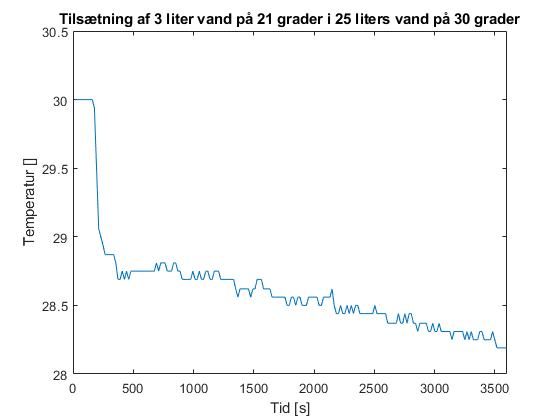


t_akse_koldt_vand = (1:length(Step_Maaling_af_30_grader_tilsat_21_grader))*(1/fs_sensor);

plot(t_akse_koldt_vand,Step_Maaling_af_30_grader_tilsat_21_grader)
title('Tilsætning af 3 liter vand på 21 grader i 25 liters vand på 30 grader')
ylim([28 30.5])
xlim([0 3600])
xlabel('Tid [s]')
ylabel('Temperatur []')

**Målt data (Proces)**

load 'WaterHeated.mat'


step_respons_temp = WaterHeated_Fake(350:1419);
t_akse_step = (1:length(step_respons_temp))*(1/fs_sensor);

plot(t_akse_step,step_respons_temp)
ylabel 'Tempertur C{\circ}'
xlabel 'Tid [s]'
title 'Åbensløjfekarakterstik Seprespons. 22.3->25.19 grader'

**Åbensløjfe-krakterstik (Proces)**


offset = 22.3 %stuetemperatur

offset = 22.3000

input = 20 %procent duty cycle

input = 20

output = 25.19-offset %vand Temperatur

output = 2.8900

Type : 2 ordens

Zeta: 0.85

Settletime Tsettle  = 16000 s

wBW (båndbredde) = Wn (naturlige frekvens)

hold on

zeta = 0.85;
Tsettle = 16000

Tsettle = 16000

wBW=(4/(zeta*Tsettle))*sqrt((1-2*zeta^2)+sqrt(4*zeta^4-4*zeta^2+2)) 

wBW = 2.3704e-04

DC_gain=output/input

DC_gain = 0.1445


Gp=(DC_gain*(wBW^2))/(s^2+s*2*zeta*wBW+wBW^2)

Gp =
 
           8.119e-09
  ----------------------------
  s^2 + 0.000403 s + 5.619e-08
 
Continuous-time transfer function.



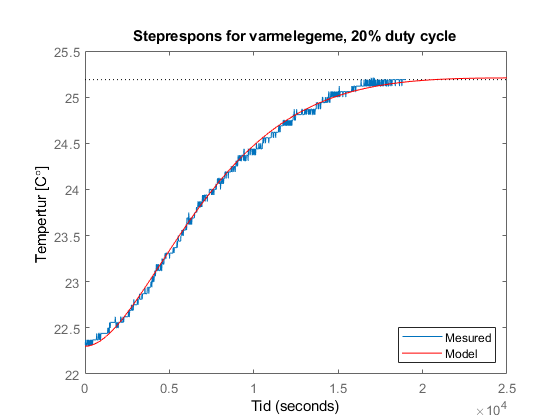


step(input*Gp+offset,'red')
legend('Mesured','Model','location','southeast')
title 'Steprespons for varmelegeme, 20% duty cycle'
ylabel('Tempertur [C{\circ}]')
xlabel('Tid')
ylim([22 25.5])
hold off

S = stepinfo(input*Gp+offset)

S = struct with fields:
        RiseTime: 1.1251e+04
    SettlingTime: 1.7675e+04
     SettlingMin: 24.9054
     SettlingMax: 25.2082
       Overshoot: 0.0721
      Undershoot: 0
            Peak: 25.2082
        PeakTime: 2.5142e+04


**Lukketsløjfe krarkterstik**

h = stepplot(feedback(Gp,1))


h =

	resppack.timeplot



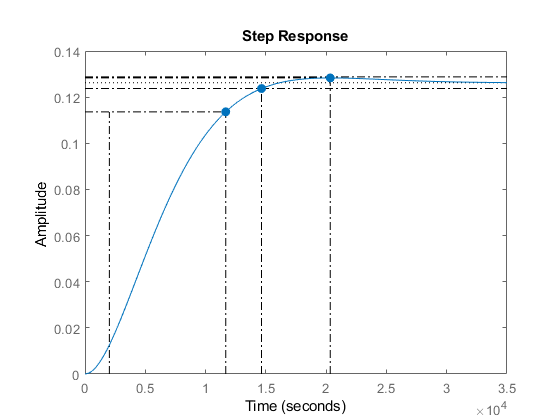

h.showCharacteristic('RiseTime')
h.showCharacteristic('SettlingTime')
h.showCharacteristic('PeakResponse')


Trise=11670-2057

Trise = 9613

Tsettle = 14640 

Tsettle = 14640

Css = 0.1263 %steady state value

Css = 0.1263

peak = 0.1283

peak = 0.1283

OS = ((0.1283-0.1263)/0.1263)*100 %procent oversving

OS = 1.5835

**Design krav**

**Ts settle time < 3600**

Den største temperaturændring systemet kan udsættes for, er tilføjelsen af tre litter væske, sammen med den naturlige tab af temperatur over en time. Dette medfølder et temperaturtap på 1.8 grader. Reguleringen designes til at have en settle time på 1 time, således de 1.8 grader kan modsvares og dermed opretholde kravet om max teperaturændring på 1 grad i timen.

**OS = 50 %**

tempraturen må MAX ændres 1 grad i timen. Dvs hvis setpoint er = 1 grad, og settletime = 3600 sekunder, tillades 0% oversving. Da dette er et max krav, desginer vi efter setpoint step på 0.5 grader, hvoraf vi tillader et oversving på OS < 50%. det vil resultere i et max peak på 0.75 grader ved step på 0.5 grader. Dette er ud fra et ønske om et hurtigt reagerende system over for eksterne forstyrelser.

**Stationær fejl < 1 %**

Da systemet ønskes at vlre præcist, designes efter en stationær fejl på udner 1%

**Identificering af fasemagen frekvesn**

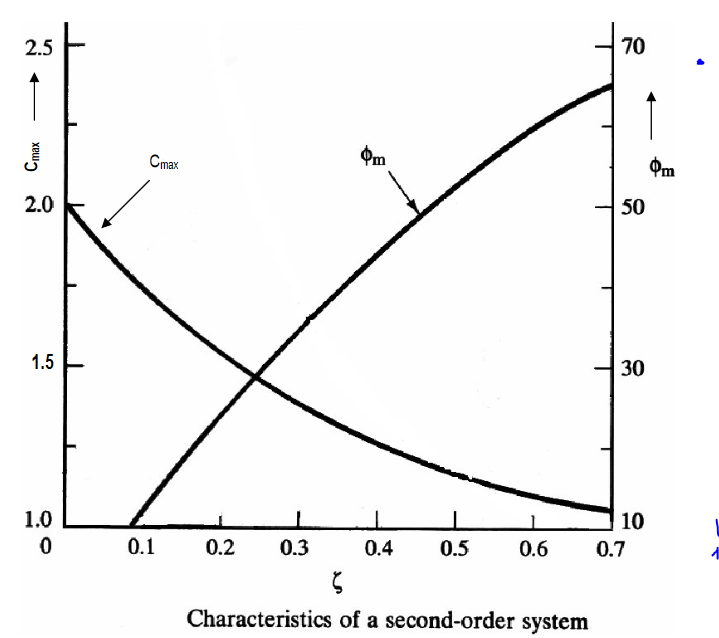

zeta = 0.25

zeta = 0.2500

Ts = 3600

Ts = 3600

pm = 30

pm = 30

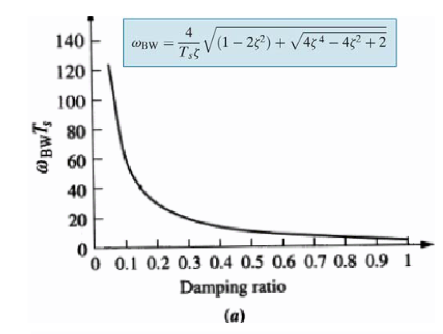

Wpm=29/Ts

Wpm = 0.0081

**Fasemagen frekvens: Kp led **

forstækningen skal løfte 77.97 db for at have 0db knægfrekvens i pasemagenfrekvensen.

Kp = 10^(78.2/20)

Kp = 8.1283e+03

Gc = Kp

Gc = 8.1283e+03

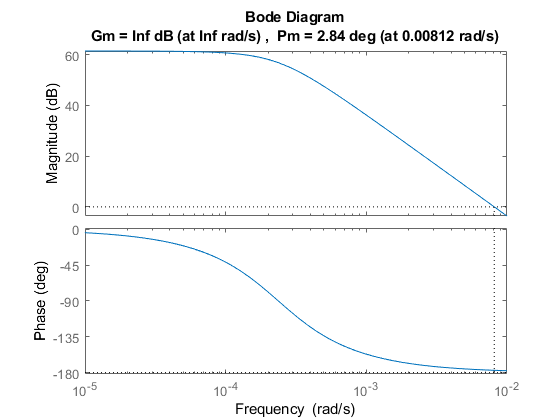

margin(Gp*Gc)

Fasemagen frekvens = OK 

Fasemagen = NOT OK

**Faseløft: Lead led**

fase = 177.1 

ønsket fase = 180 - fasemagen(pm) = 150

faseløft =  177.1-150 = 27.1

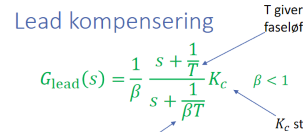

Wpm = 8.1*10^-3

Wpm = 0.0081

beta = (1-sind(27.1))/(1+sind(27.1))

beta = 0.3741

T = 1/(Wpm*sqrt(beta))

T = 201.8584

Kc = sqrt(beta)

Kc = 0.6116


Glead = (1/beta)*((s+(1/T))/(s+(1/(beta*T))))*Kc

Glead =
 
  1.635 s + 0.0081
  ----------------
    s + 0.01324
 
Continuous-time transfer function.




Gc = Kp*Glead

Gc =
 
  1.329e04 s + 65.84
  ------------------
     s + 0.01324
 
Continuous-time transfer function.



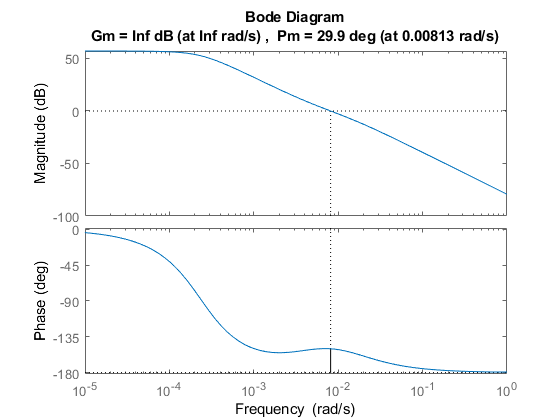

margin(Gp*Gc)

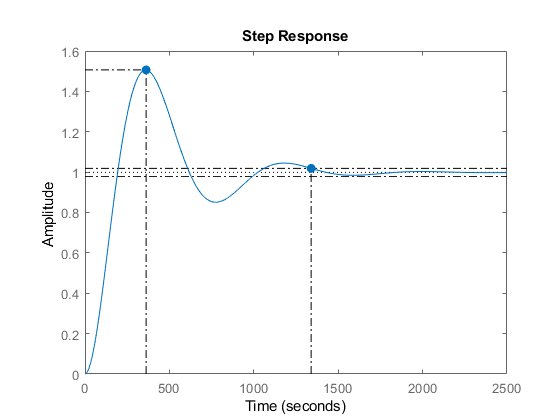


h = stepplot(feedback(Gp*Gc,1));
h.showCharacteristic('SettlingTime')
h.showCharacteristic('PeakResponse')

Fasemagen frekvens = OK 

Fasemagen = OK

Ts = 1340 (OK!!! :D)

OS = 50% (OK)

**Digitalisering**

Åstrøm og wittenmark

0,15/wpm < Ts < 0.5/wpm

Ts_min = 0.15/Wpm

Ts_min = 18.5185

Ts_max = 0.49/Wpm; %0.5 er max og giver ustabilt system


Time delay: fra sampling

[num, den] = pade(Ts_max/2,3);
Td_max=tf(num,den);

[num, den] = pade(Ts_min/2,3);
Td_min=tf(num,den); 

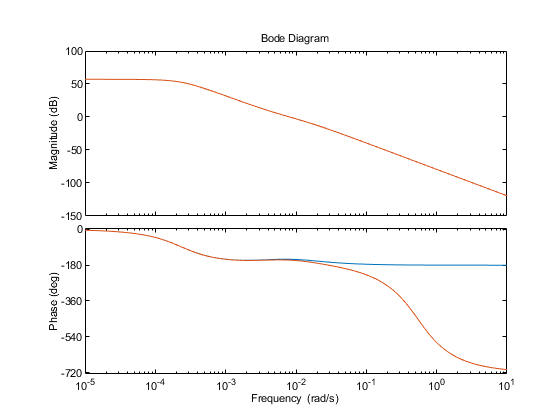

PP = bodeoptions;
PP.PhaseMatching= 'on';
PP.PhaseMatchingValue=0;
bode(Gp*Gc, PP)
hold on
bode(Gp*Gc*Td_min, PP)
hold off

Der tages udgangspunkt i den hurtigste samplingtid: Ts minimum i alle digitaletransformationer

digitalisering af Regulator (Gc) Bilineartransformation

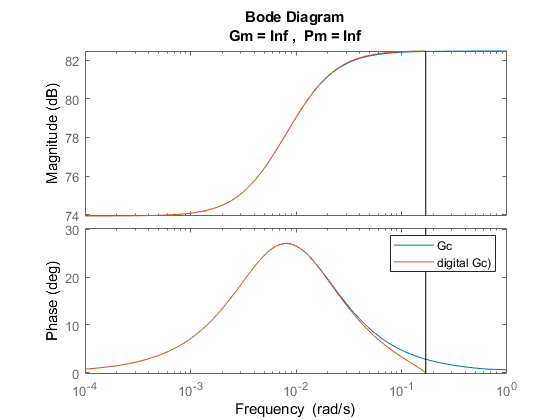

Gc_TsMin=c2d(Gc,Ts_min,'tustin');
bode(Glead*Kp)
hold on
margin(Gc_TsMin)
legend('Gc','digital Gc)')
hold off

Sampling af proces (Gp) og medhørende time delay (Gsh). zero order hold

Gsh_min=c2d(Gp,Ts_min,'zoh'); %%ligger sampling delay med (INGEN Td_MIN)

Overføringsfunktion for Gp samplet * Gc digitaliseret

Gz = Gsh_min*Gc_TsMin

Gz =
 
  0.01719 z^2 + 0.001466 z - 0.01565
  ----------------------------------
  z^3 - 2.774 z^2 + 2.55 z - 0.7757
 
Sample time: 18.519 seconds
Discrete-time transfer function.



Bode plot afsløre fasemagnen er faldet til 21.3 grader efter systemet er digitaliseret.

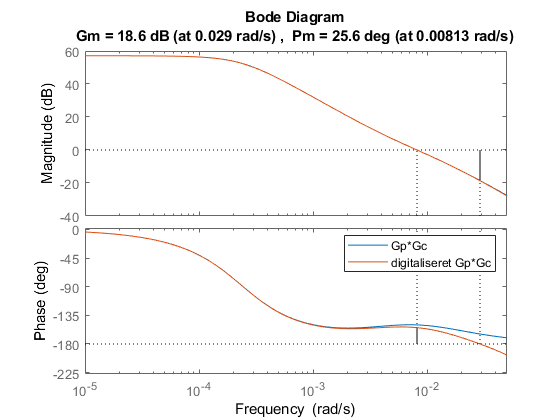

bode(Gc*Gp)
hold on
margin(Gz)
xlim([10^-5 5*10^-2])
legend('Gp*Gc', 'digitaliseret Gp*Gc')
hold off

Dette kan ses på stepresponset, som at oversvinget er blevet større:

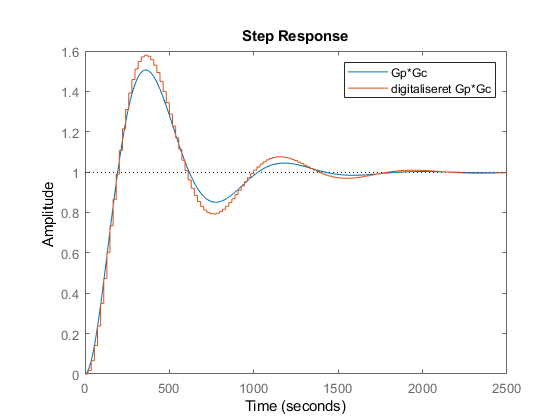

step(feedback(Gc*Gp,1))
hold on
step(feedback(Gz,1))
legend('Gp*Gc', 'digitaliseret Gp*Gc')
hold off

Derfor må lead kompenseringnen tunes så den udligner digitaliseringens biddag til fasemagnen.

pmLoss = 30-21.3

pmLoss = 8.7000

(ved indspektion findes et faseløft på 19 grader, og altså en fasemagen på 31.6 grader total, til at være PERFEKT!)

**Lead tuning**

beta = (1-sind(27.1+pmLoss))/(1+sind(27.1+pmLoss));
T = 1/(Wpm*sqrt(beta));
Kc = sqrt(beta);
Glead_tuned = (1/beta)*((s+(1/T))/(s+(1/(beta*T))))*Kc;

Gc_tuned = Kp*Glead_tuned;

**Overføringsfunktion for Gp samplet * Gc tuned digitaliseret**

Gc_min_tuned=c2d(Gc_tuned,Ts_min,'tustin');

Gz_tuned = Gc_min_tuned*Gsh_min

Gz_tuned =
 
  0.01998 z^2 + 0.001427 z - 0.01845
  ----------------------------------
  z^3 - 2.737 z^2 + 2.476 z - 0.7388
 
Sample time: 18.519 seconds
Discrete-time transfer function.



Det ses på bodeplottet at fasemagnen nu overholder de 30 grader

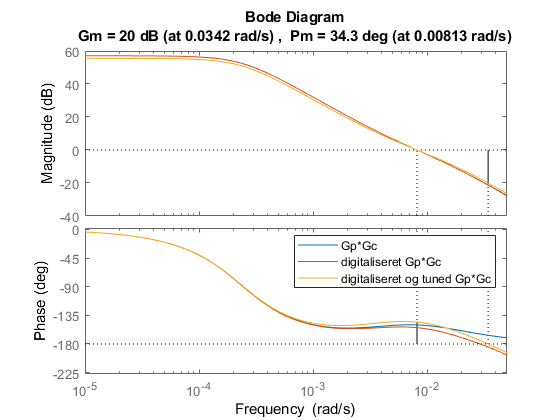

bode(Gp*Gc)
hold on
bode(Gz)
margin(Gz_tuned)
xlim([10^-5 5*10^-2])
legend('Gp*Gc','digitaliseret Gp*Gc','digitaliseret og tuned Gp*Gc')
hold off

Også stepresponset er tilbage p de 50% oversving

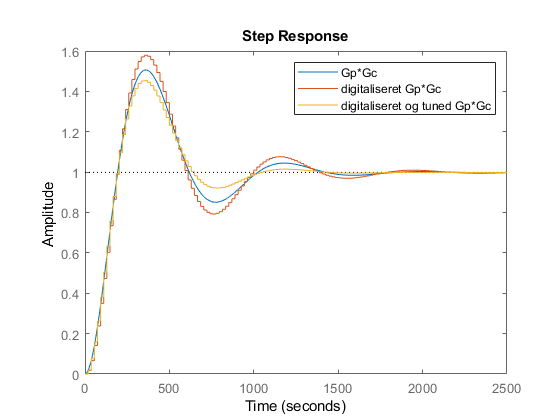

step(feedback(Gc*Gp,1))
hold on
step(feedback(Gz,1))
step(feedback(Gz_tuned,1))
legend('Gp*Gc', 'digitaliseret Gp*Gc', 'digitaliseret og tuned Gp*Gc')
hold off

**Regulator Overføringsfunktion**

Gc_min_tuned

Gc_min_tuned =
 
  1.439e04 z - 1.332e04
  ---------------------
       z - 0.7443
 
Sample time: 18.519 seconds
Discrete-time transfer function.



Input til proces

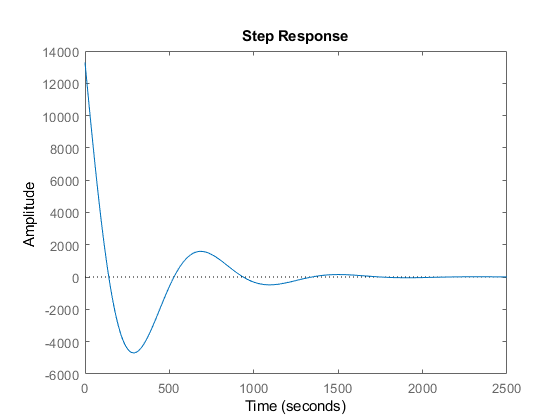

step(feedback(Gc,Gp))

Det bliver sku svært at sætte in duty cycle på 13000% :(

DET SKAL LAVES OM DU!

# **Version 2**

duty_cycle = 8.3

duty_cycle = 8.3000

Start temperatur = 30 grader. tilføjelse af 3 litter vand, biddager med et temperatur tap på 1.2 grader. Derfor ses steppet som 28.8 grader -> 30 

step på 1.2 grader, tilsvare et step på 8.3 % dutycylce 

28.8 grader = 

duty_cycle = 8.3

duty_cycle = 8.3000

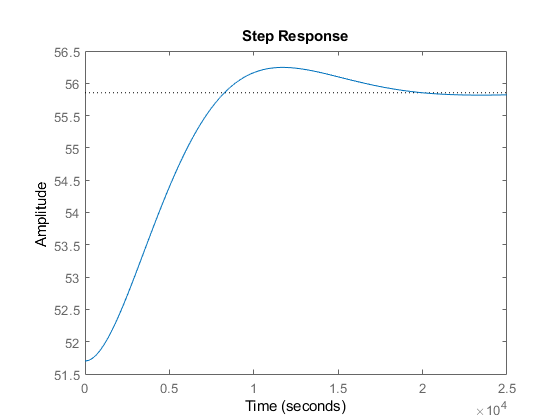


hold off

step(28.8+duty_cycle*Gp)


introducering af feed back og regulering med kp = 1

Kp_dum = 1

Kp_dum = 1


hold on
step(28.8+duty_cycle*feedback(Gp*Kp_dum,1))

Kp ændres til 1.17

Kp_dum = 1.17

Kp_dum = 1.1700


step(28.8+duty_cycle*feedback(Gp*Kp_dum,1))
legend ('åbensløje', 'lukketsløjfe kp = 1', 'lukketsløjfe kp =1.17', "Location","southeast")
hold off 

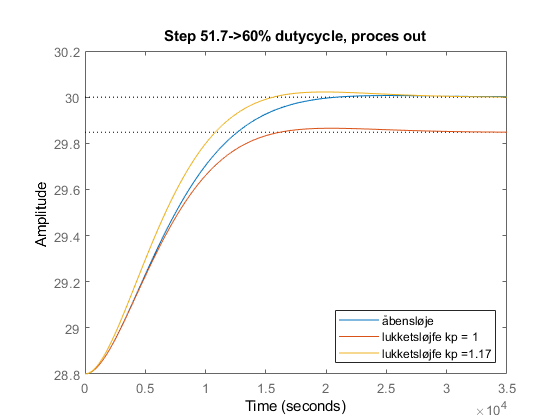

title 'Step 51.7->60% dutycycle, proces out'

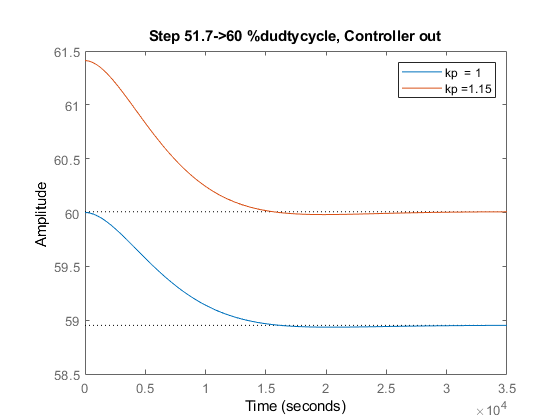

step(51.7+duty_cycle*feedback(1,Gp))
hold on
step(51.7+duty_cycle*feedback(Kp_dum,Gp))
title 'Step 51.7->60 %dudtycycle, Controller out'
legend ('kp  = 1', 'kp =1.15')
hold off

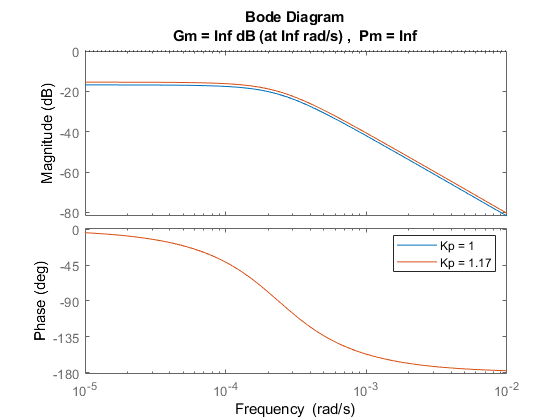

margin(Gp*1)
hold on
margin(Gp*Kp_dum)
legend('Kp = 1', 'Kp = 1.17')
hold off

Rise time er = 10.000 sekunder

Den ønskes atvære 8000 sekunder

OS = 10%

zeta = 0.55 % OS

zeta = 0.5500

Tr=6000

Tr = 6000

WBW = zeta/Tr

WBW = 9.1667e-05

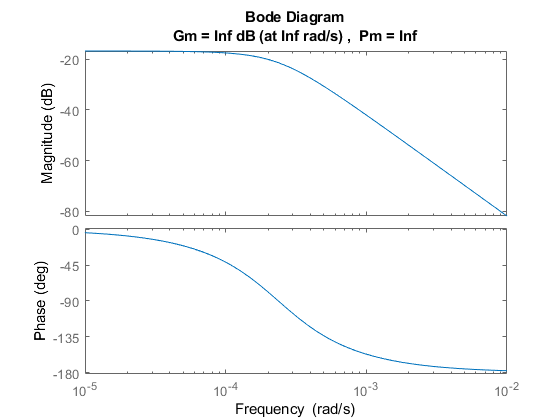

margin(Gp*1)

Fasemagen frekvens på 1.875*10^-5 giver et db løft på 16.82

Kp = 10^(17.13/20)

Kp = 7.1862

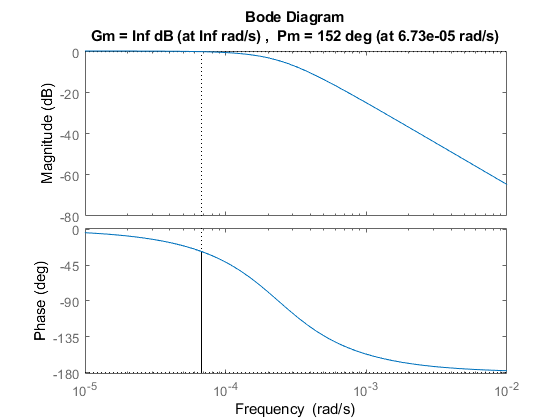

margin(Gp*Kp)

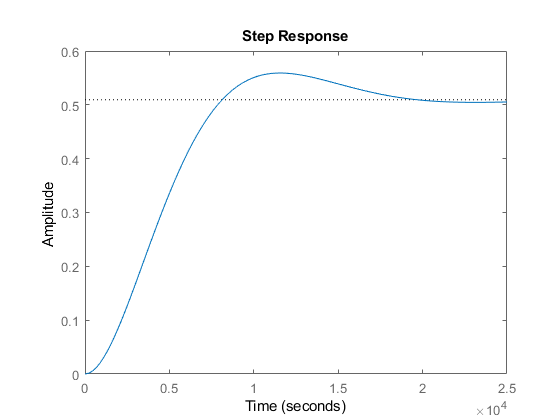

step(feedback(Kp*Gp,1))

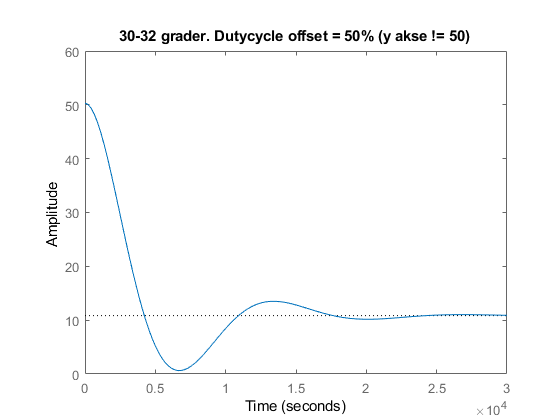


step(2*feedback(Kp*3.5,Gp))
title '30-32 grader. Dutycycle offset = 50% (y akse != 50)'

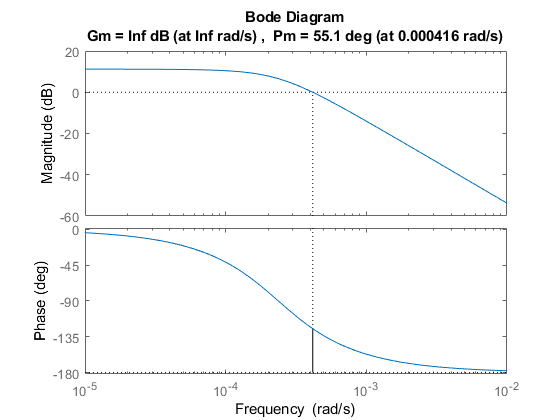


margin(Kp*3.5*Gp)

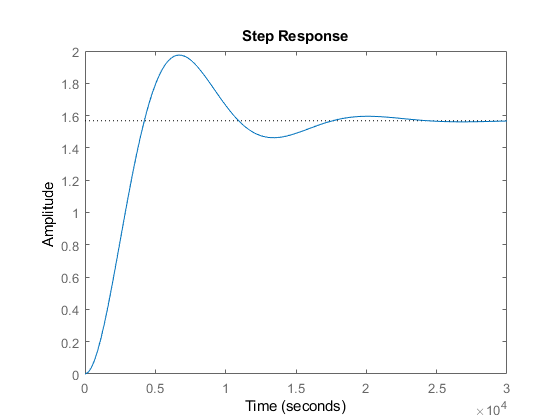

step(2*feedback(Kp*3.5*Gp,1))

Tr = 0.000416*zeta

Tr = 2.2880e-04

stationær fejl = 20%

**Lag**

T = 20/0.000416

T = 4.8077e+04

a = 100 %stationær fejl  = 1%

a = 100

Glag = (s+(1/T))/(s+1/(a*T))

Glag =
 
  s + 2.08e-05
  ------------
  s + 2.08e-07
 
Continuous-time transfer function.



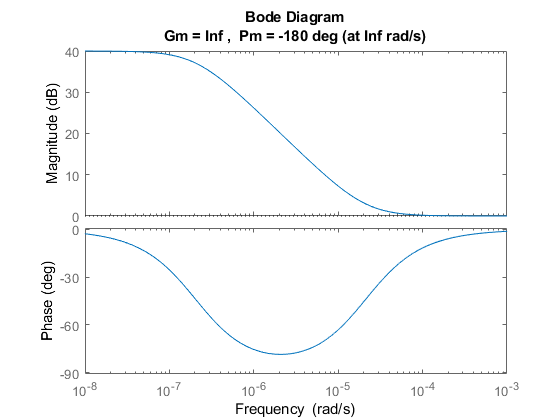


margin(Glag)


2*(1/(1+10^(40/20))) %staionær fejl (gange 2 forstep størelse (temp på 2 grader))

ans = 0.0198

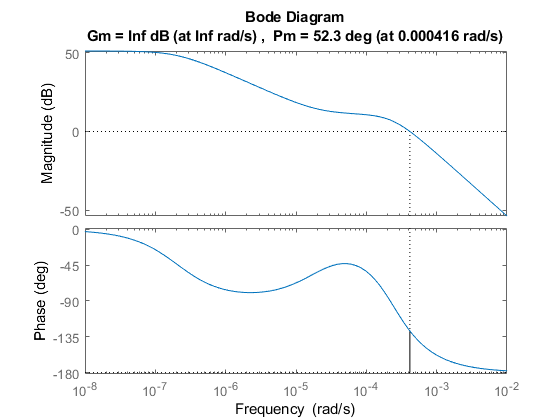


margin(Glag*Gp*3.5*Kp) %fasenmagen falder 3 grader... peanut

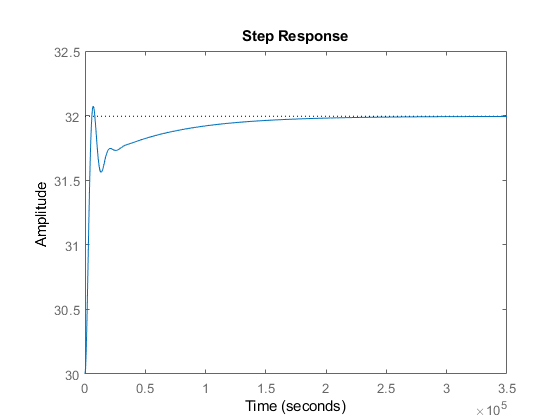

step(2*feedback(Glag*Gp*3.5*Kp,1)+30) %

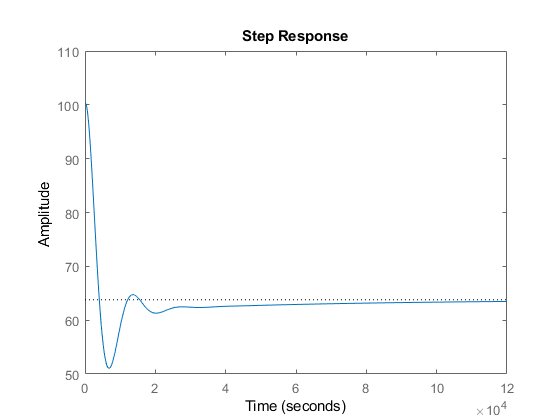

step(2*feedback(Glag*3.5*Kp,Gp)+50)

Rate limiter - rampe begrænser

25 -> 30

step 0.1 -> regulator

vent 10 min

25.1 -> 30

step 0.1 -> regulator

25.2 -> 30

vent 10 min ......

integrator logik, max 100% 

PI 

Opdater ikke integral, hvis control isgnal er under 100% (anti Winde up)

Plot

hold off

step(28.8+duty_cycle*Gp)
Kp_dum = 1

Kp_dum = 1

hold on
step(28.8+duty_cycle*feedback(Gp*Kp_dum,1))
Kp_dum = 1.17

Kp_dum = 1.1700

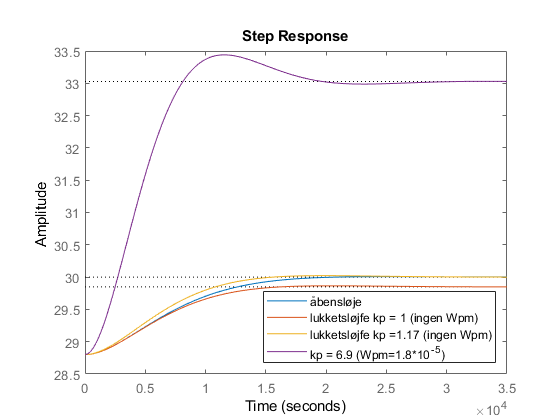

step(28.8+duty_cycle*feedback(Gp*Kp_dum,1))
step(28.8+duty_cycle*feedback(Gp*Kp,1))
legend ('åbensløje', 'lukketsløjfe kp = 1 (ingen Wpm)', 'lukketsløjfe kp =1.17 (ingen Wpm)', 'kp = 6.9 (Wpm=1.8*10^-^5)', "Location","southeast")
hold off 

Lag

T = 0.5/10^-3

T = 500

a = 100*Kp_dum

a = 117

Glag = (s+1/T)/(s+1/(a*T))

Glag =
 
    s + 0.002
  -------------
  s + 1.709e-05
 
Continuous-time transfer function.



Kp_dum_tuned = Kp_dum * 0.01

Kp_dum_tuned = 0.0117

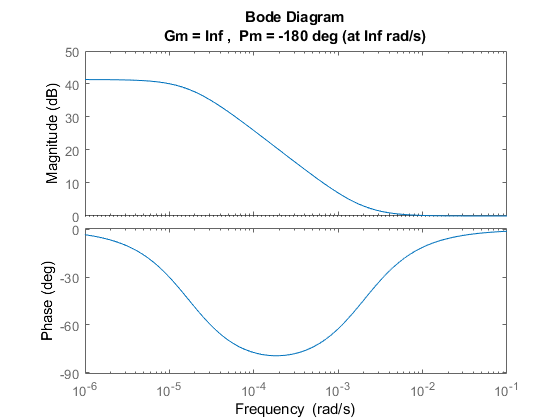


margin(Glag)

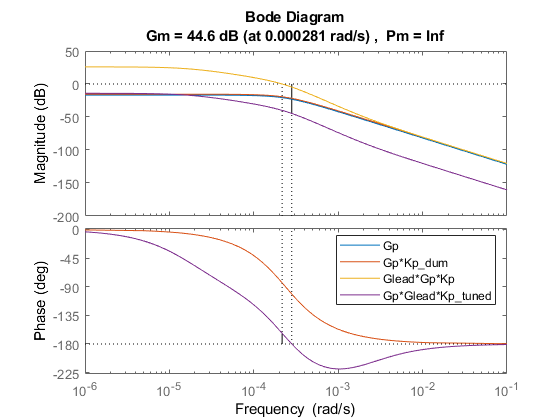

bode(Gp)
hold on
bode(Gp*Kp_dum)
margin(Glag*Kp_dum*Gp)
margin(Glag*Kp_dum_tuned*Gp)
legend('Gp','Gp*Kp_dum','Glead*Gp*Kp', 'Gp*Glead*Kp_tuned')
hold off

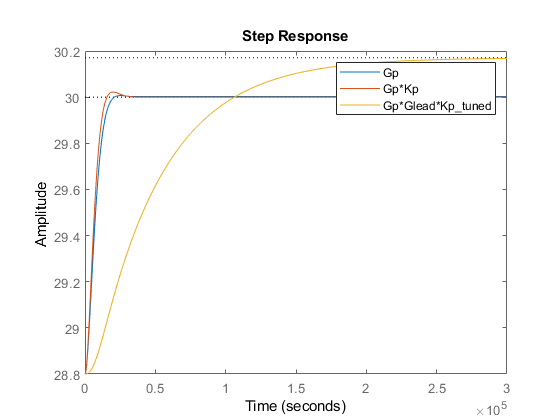


step(28.8+duty_cycle*Gp)
hold on
step(28.8+duty_cycle*feedback(Gp*Kp_dum,1))
step(28.8+duty_cycle*feedback(Glag*Gp*Kp_dum_tuned,1))
legend('Gp','Gp*Kp', 'Gp*Glag*Kp_tuned')
hold off

# **Version 3**

**%OS = 20 = C_max = 1.2**

 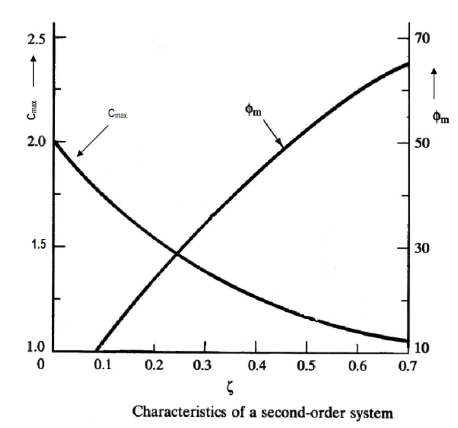

Vi vil altså gerne have en zeta på 0,55 

og en fasemargin på 58

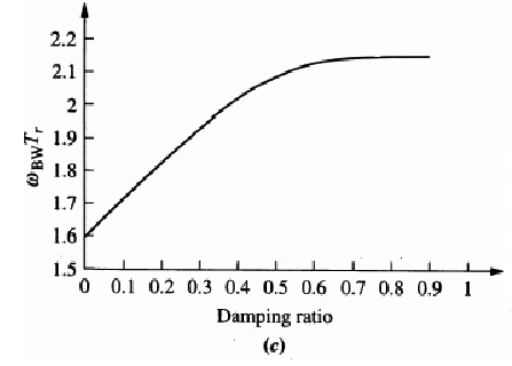

bw*Tr = 2.1

h = stepplot(feedback(Gp,1))


h =

	resppack.timeplot



h.showCharacteristic('RiseTime')
h.showCharacteristic('SettlingTime')
h.showCharacteristic('PeakResponse')

rise time lige nu = 10000 sek = 2,7 timer

vi vil gerne have en rise time. Af bitter erfaring har vi fundet ud af, at vi nok ikke kan øge den til mirakuløse små størrelser, så vi er påpasselige.

Så det sætter et krav til bw=

%%%% vi prøver uden DC gain i processen %%%%%

T_r=2.5*60*60; %ønsket rise time
bw=2.1/T_r;
ny_gp=Gp/0.14;
margin(Gp)

der skal forstærkes 4,4 dB for at få den ønskede fasemarginfrekvens

Kp=10^(4.4/20)

Kp = 1.6596

Gc=ny_gp*Kp

Gc =
 
              1.347e-08
  ----------------------------------
  0.14 s^2 + 5.642e-05 s + 7.866e-09
 
Continuous-time transfer function.



Der testes:

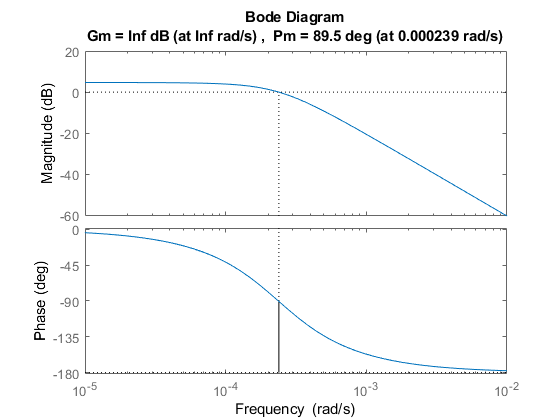

margin(ny_gp*Kp)

Det ser OK ud. 

Lukketsløjfe:

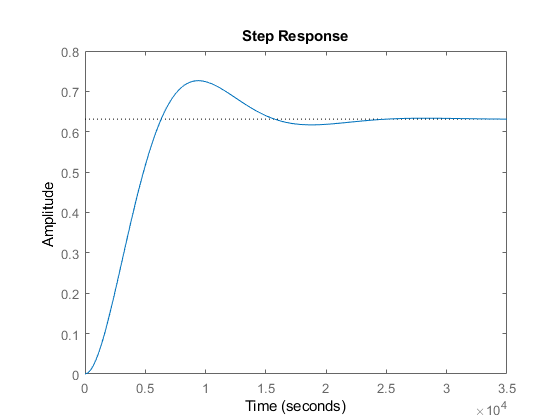

step(feedback(Gc,1))